close all;
L_0=9*10^-9;
E_g_GaAs=1.424;
E_g_InAs=0.354;
me_eff=0.067;
mh_eff=0.45;
m_0=9.1093837*10^(-31);
hbar=1.0545718*10^(-34);
mu=1/(1/(m_0*me_eff)+1/(m_0*mh_eff));
q=1.60217663*10^-19;
n=sqrt(3);
xeta=0.02;
V_e=(E_g_GaAs-E_g_InAs)*0.6*1.602176634*10^-19 ;
V_h=(E_g_GaAs-E_g_InAs)*0.4*1.602176634*10^-19 ;
P_e=((2*m_0*me_eff*V_e)^0.5/hbar)*L_0/2

P_e = 4.7814

P_h=((2*m_0*mh_eff*V_h)^0.5/hbar)*L_0/2

P_h = 10.1176

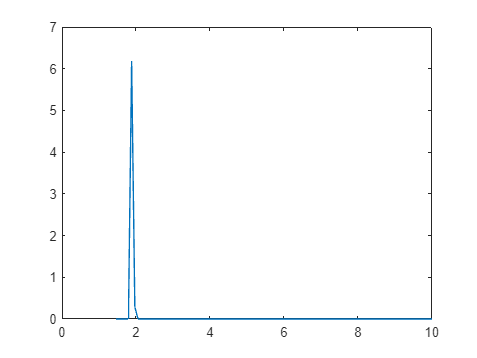

E_e=(2*(P_e/(P_e+1))^2)*(((n*pi)/2)^2-((n*pi)/2)^4)*(1/(3*(P_e+1))^3-((n*pi)/2)^6*((27*P_e-8)/(180*(P_e+1)^6)));
E_h=(2*(P_h/(P_h+1))^2)*(((n*pi)/2)^2-((n*pi)/2)^4)*(1/(3*(P_h+1))^3-((n*pi)/2)^6*((27*P_h-8)/(180*(P_h+1)^6)));
photon_energy=linspace(1.45,10);
x=photon_energy-E_g_GaAs;
eta_1=sqrt((x*n^2)/(E_e+E_h));
Reduced_energy=eta_1.^2;
photon_energy_1=E_e+E_h+E_g_InAs;


relative_absorption_0=(1/(xeta*n.^2)).*exp((-(n./eta_1-1).^2)./(2*xeta^2));
plot(photon_energy,relative_absorption_0)
hold on